# Multiple histograms - but make it easy

clear; clc;
cd('/Users/duncan/Documents/GitHub/plotMultipleHists-matlab')

## Generate some data

A = normrnd(3,1, [15, 1]);
B = normrnd(3.9, 0.2, [15, 1]);

## Method

### Plot each individually to get individual bin edges 

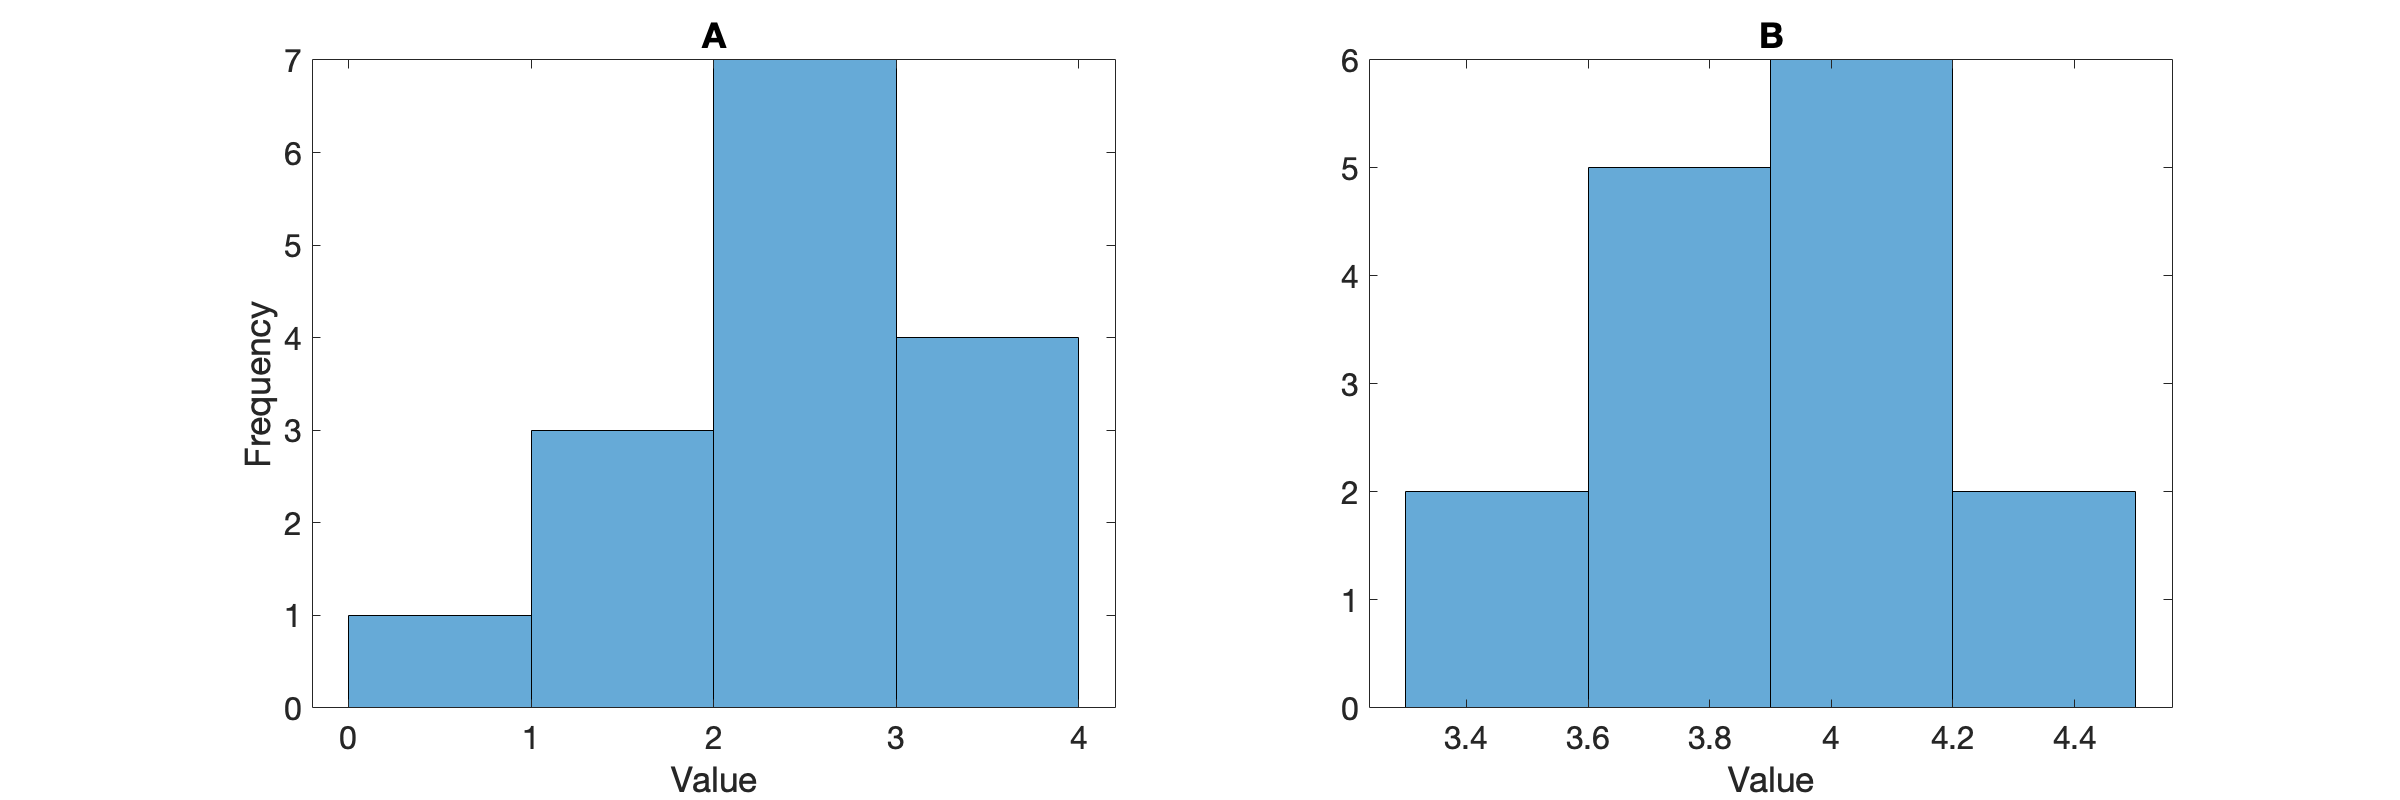

figure('position', [300 300 1200 400]);
subplot(1,2,1)
hA = histogram(A);
ylabel('Frequency');
xlabel('Value')
title('A')
set(gca, 'fontsize', 16)
subplot(1,2,2)
hB = histogram(B);
title('B')
xlabel('Value')
set(gca, 'fontsize', 16)

### Calculate distances between edges

disthA = mean(diff(hA.BinEdges))

disthA = 1

disthB = mean(diff(hB.BinEdges))

disthB = 0.3000

bEdgeStep = min([disthA disthB])

bEdgeStep = 0.3000

### Determine largest x limits 

hAlim = hA.BinLimits

hAlim =      0     4


hBlim = hB.BinLimits

hBlim =     3.3000    4.5000


bLims = [(min([hAlim, hBlim])), max([hAlim, hBlim])]

bLims =          0    4.5000


bEdges = bLims(1):bEdgeStep:bLims(2); 

### Replot on the same figure using smaller bin edges, lower alpha, and max xlimits 

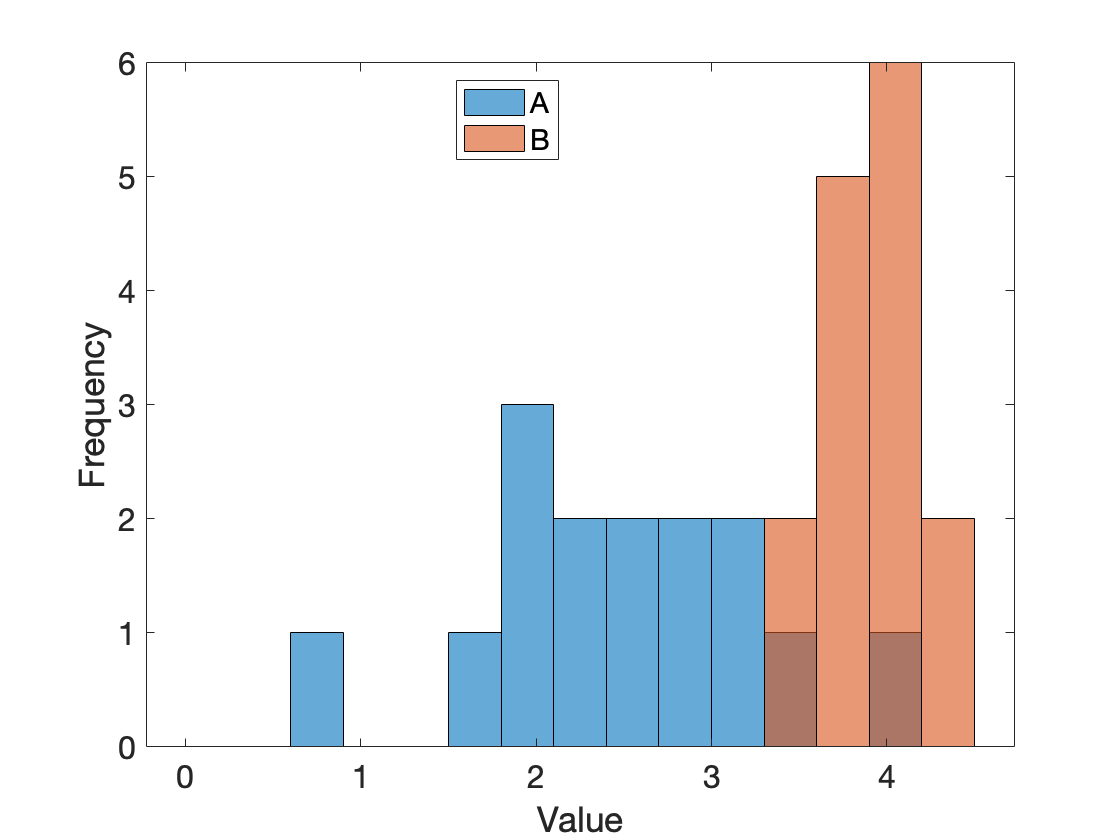

figure(); 
histogram(A, "BinLimits", bLims, 'BinEdges', bEdges, 'displayname', 'A'); 
hold on
histogram(B, "BinLimits", bLims, 'BinEdges', bEdges, 'displayname', 'B'); 
legend('location', 'best')
xlabel('Value')
ylabel('Frequency')
set(gca, 'fontsize', 16)

## Call function (works for N data vectors) 

### 2 data vectors 

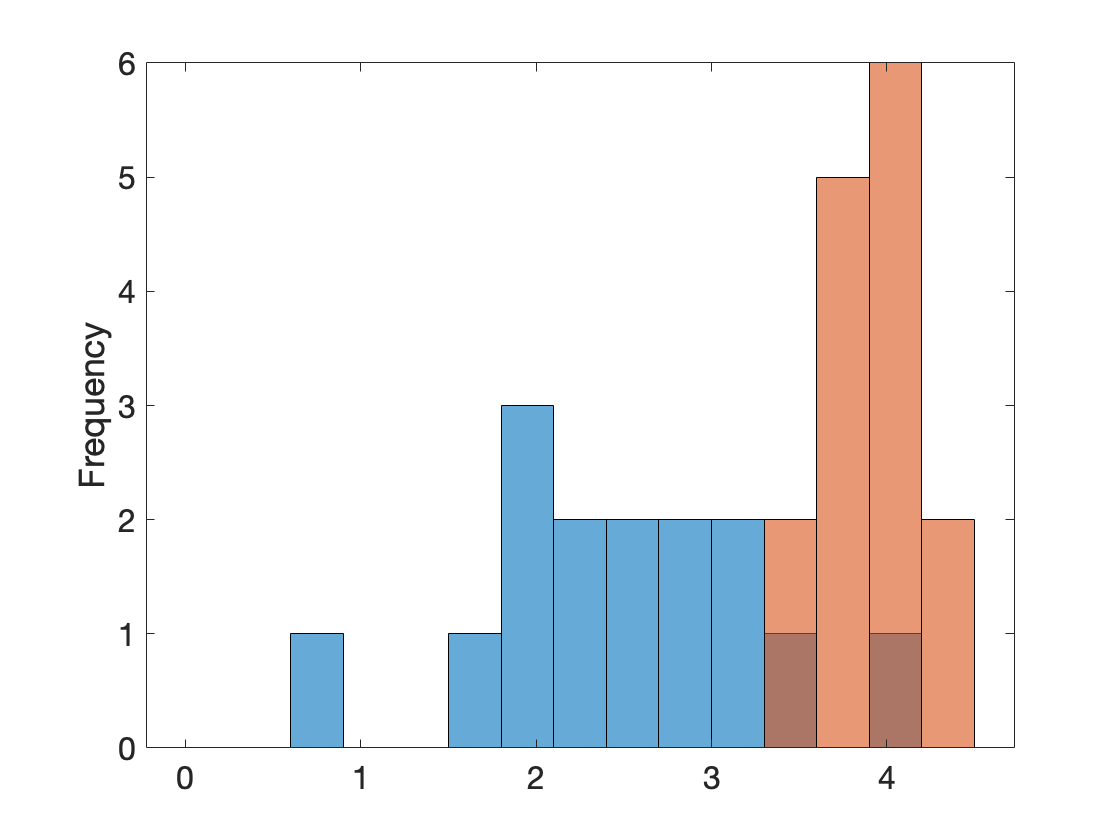

plotMutlipleHists(A, B)

ax(1) = gca(); 

### 3 data vectors

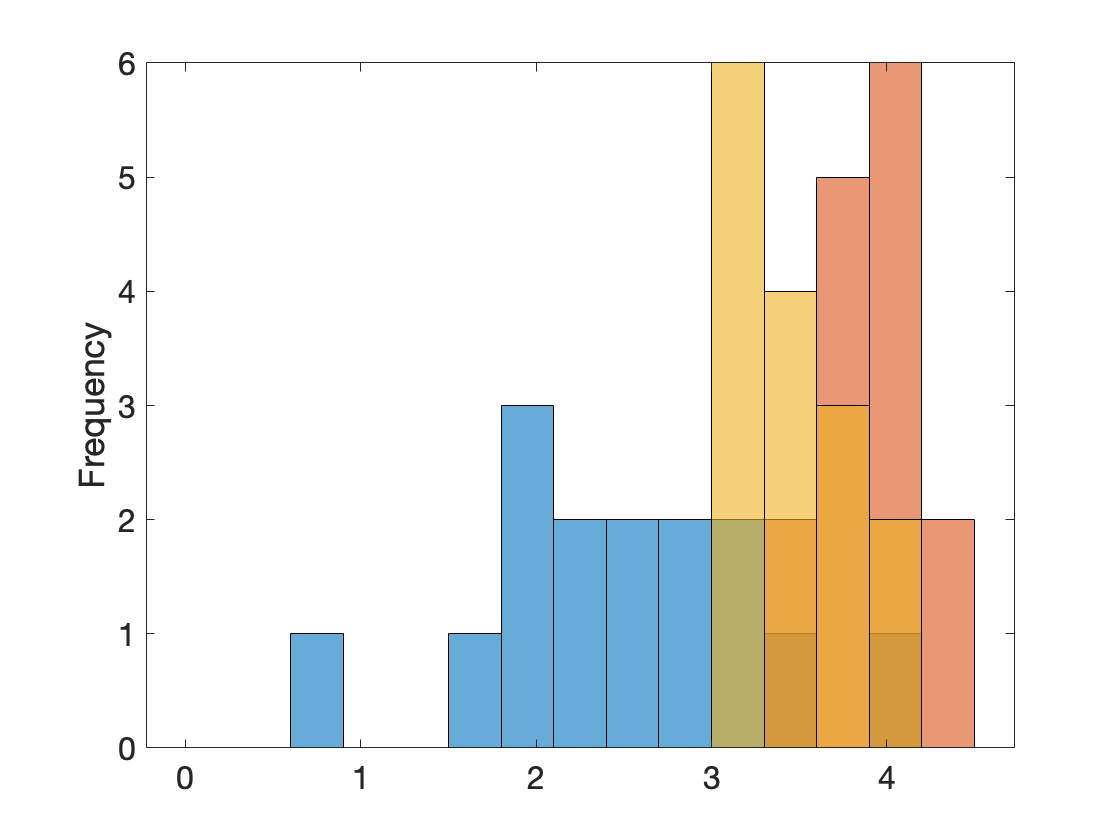

C = normrnd(3.5, 0.3, [15, 1]);
plotMutlipleHists(A, B, C)

ax(2) = gca(); 

### 4 data vectors 

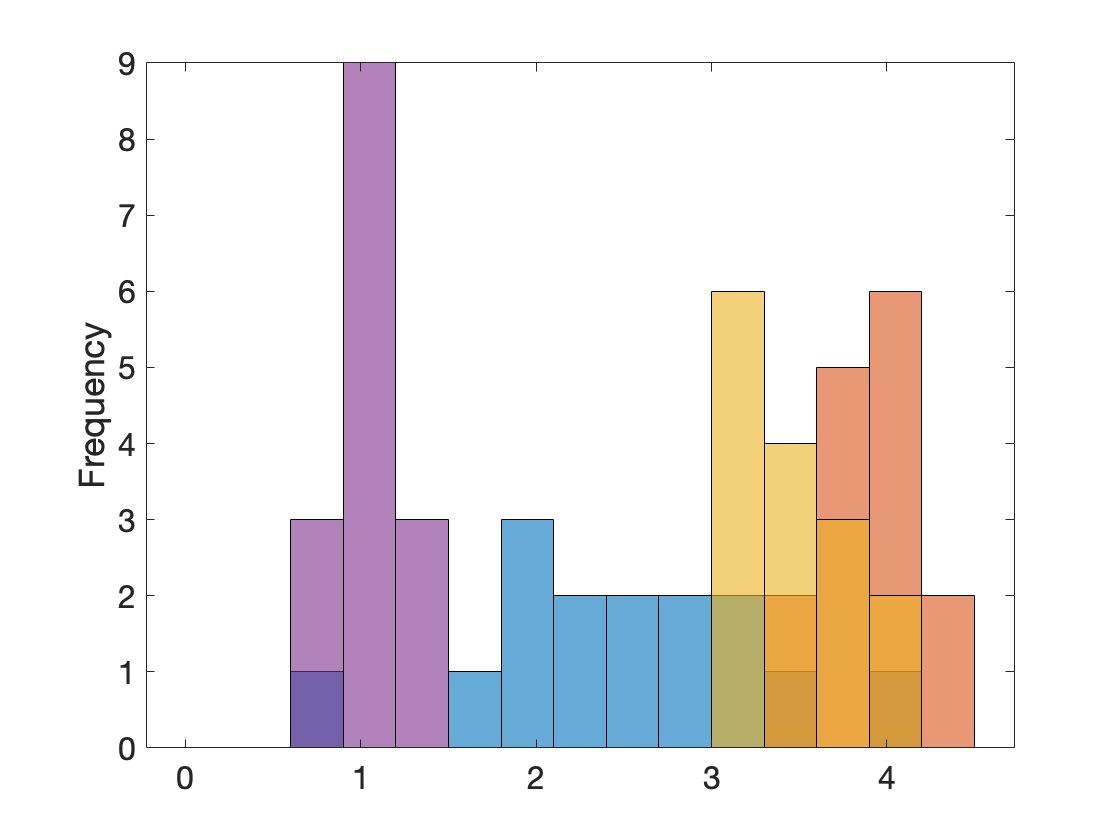

D = normrnd(1, 0.2, [15, 1]);
plotMutlipleHists(A, B, C, D)

ax(3) = gca(); 

### 5 data vectors

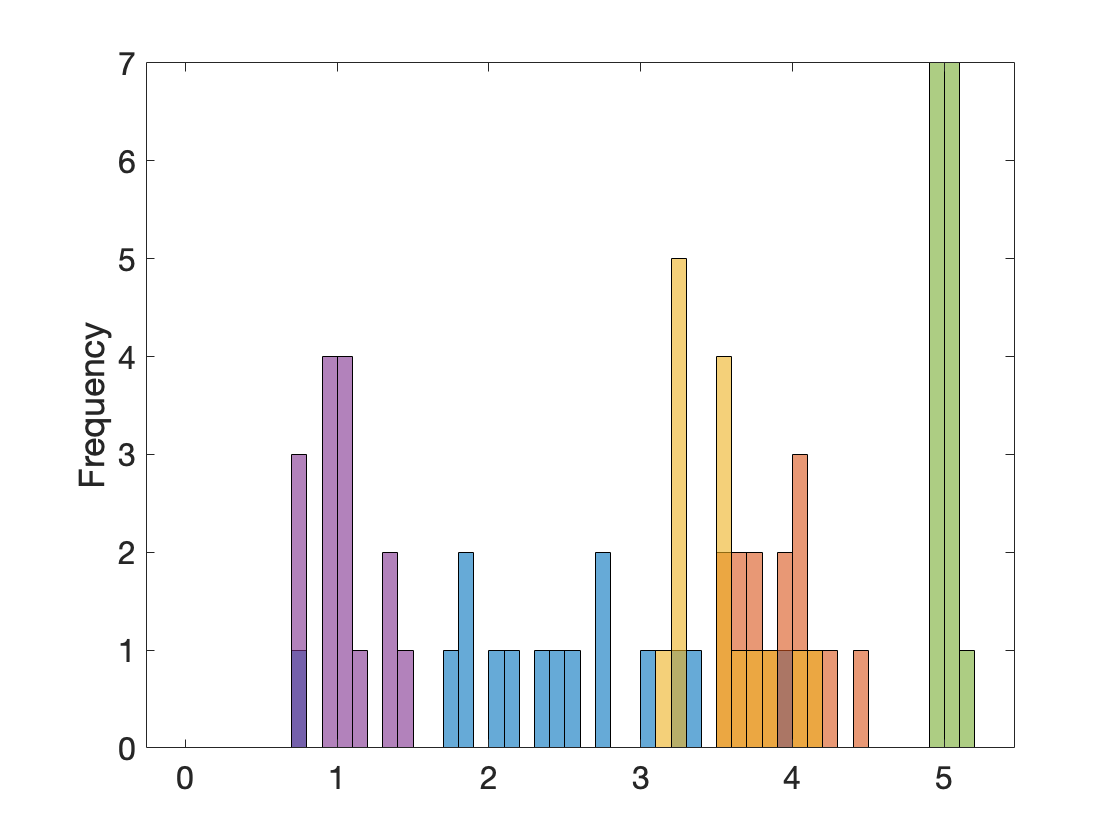

E = normrnd(5, 0.1, [15, 1]);
plotMutlipleHists(A, B, C, D, E)

ax(4) = gca(); 
% % subplot them 
% figure('position', [300 300 1200 400]);
% for i = 1:4
%     axSP(i) = subplot(2,2,i, 'parent', gcf());
% end
% for i = 1:4
%     axcp = copyobj(ax(i), gcf());
%     set(axcp, 'position', get(axSP(i), 'position'));
%     delete(axSP(i)); 
% end